rng(100);
class1=mvnrnd([1 3],[1 0; 0 1],60);
class2=mvnrnd([4 1],[2 0; 0 2],40);
y = [ones(60,1); -ones(40,1)];
data = [class1;class2];
[N,l] = size(data);
a = [data ones(N,1)];

h = eye(l);
H = [h zeros(l,1); zeros(1,l+1)];

f = zeros(l+1,1);
A = a.*-y;

% H = A.'*A;

b = -ones(N,1);


w = quadprog(H,f,A,b);


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>


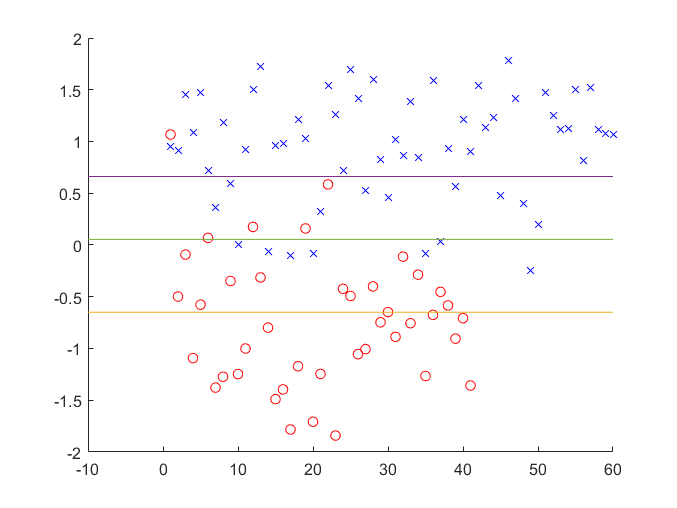


y1 = a(1:60,:)*w;
y2 = a(60:100,:)*w; 

bound = @(tt) (-(w(2)*tt)/w(1)) - w(3)/w(1);
hold on
plot(y1,'bx')
plot(y2,'ro')
fplot(W)

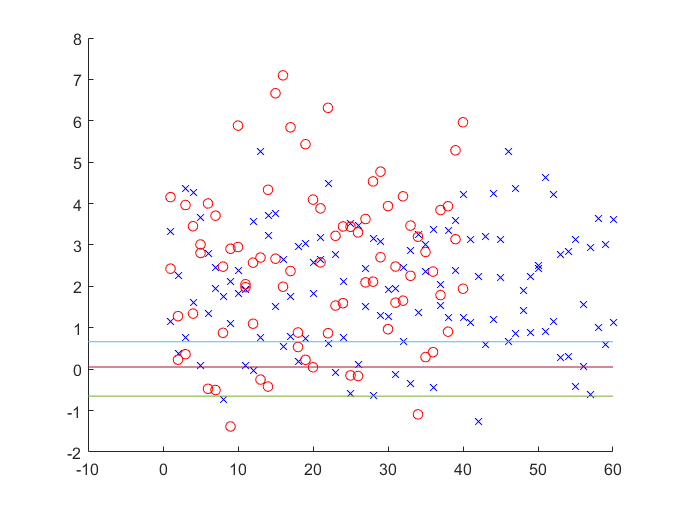


figure()

hold on
plot(class1,'bx')
plot(class2,'ro')
fplot(W)

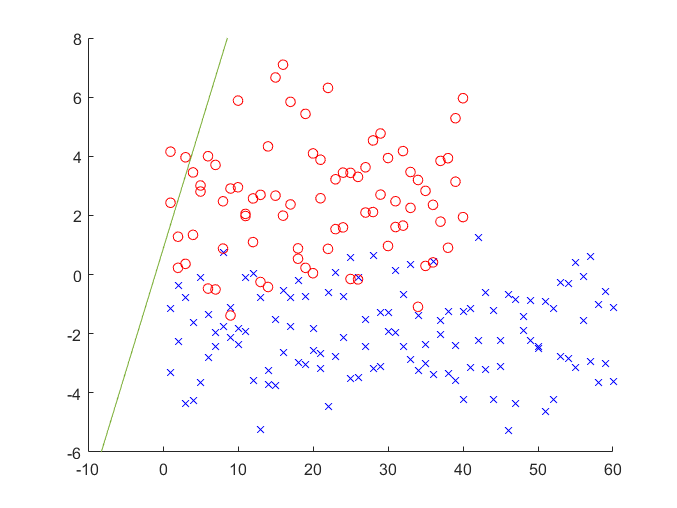


figure()

hold on
plot(-class1,'bx')
plot(class2,'ro')
fplot(bound)


% sumb = zeros(1,N);
% for i = 1:N
%     suma = zeros(1,N);
%     for j = 1:N
%         suma(i) = suma(i) + (y(i)*y(j)*dot(data(i),data(j)));
%     end
%     sumb(i) = suma(i);
% end
% h = sum(sumb,'all')
% quadprog(h,-1)